# Signal Modulation Classification with *RadioML* 

This project focuses on the classification of radio signal modulations using deep learning techniques. Specifically, leveraging the RadioML dataset, which contains a variety of signal types, to train and evaluate Convolutional Neural Networks (CNNs) effectiveness in distinguishing between different modulation schemes. The classification task is critical in cognitive wireless communication systems, enabling robust and efficient signal processing and decision making within a network.

### **Dataset**

- **Name**: RadioML Dataset by DeepSig

- **Source**: 

- **Description**: RadioML includes a mix of synthetic and over-the-air signals. The signal generation process involves pulse shaping, interpolation, and frequency mixing. A Rayleigh Channel Impulse Response simulates multipath fading, and additive Gaussian white noise (AGWN) is applied

- **Format**: HDF5

- **Size**: 3GB

## Load Dataset

RadioML Dataset obtained is in HDF5 file format, hence we use MATLAB's `h5read` helper to parse and read the content of the file. To systematically read the content of the radioML file, we implemented a RadioMLDatastore & MiniBatchDatastore which are instances of `matlab.io.Datastore` library. With RadioMLDatastore and `h5read helper library`  we can choose parameters that determine how we read the dataset. Parameters such as **Start Position**, **Strides**, and **Size **are the available degrees of freedom.

filePath = "./GOLD_XYZ_OSC.0001_1024.hdf5";

% parameters to extract one signal per modulation scheme for each dataset read
batchSize = 24;
stride = 106497;
start = 65537;

% initialize a datastore for testing and data exploration 
testDs = RadioMLDatastore(filePath, "/X", "/Y", "test", batchSize, stride, start);
testMbds = MiniBatchDatastore(testDs, 24);
data = testMbds.read()

data = 24×2 table
      Predictors       Response
    _______________    ________

    1×1024×2 single    OOK     
    1×1024×2 single    4ASK    
    1×1024×2 single    8ASK    
    1×1024×2 single    BPSK    
    1×1024×2 single    QPSK    
    1×1024×2 single    8PSK    
    1×1024×2 single    16PSK   
    1×1024×2 single    32PSK   
    1×1024×2 single    16APSK  
    1×1024×2 single    32APSK  
    1×1024×2 single    64APSK  
    1×1024×2 single    128APSK 
    1×1024×2 single    16QAM   
    1×1024×2 single    32QAM   
    1×1024×2 single    64QAM   
    1×1024×2 single    128QAM  


% extract all modulation schemes present in dataset
allModulations = categorical(data{:, 2});

#### Dataset Subset

In this project, we reduce the scope of the problem by selecting only a subset of the modulation schemes found in the RadioML Dataset. This subset was choosen by picking the most commonly found modulation schemes in radio spectrum in urban areas.

% selected modulation types
selectedModIdx = [4 5 13 15 6 2 3 23 18 19 22];

modulationTypes = cell(1, 11);
for i=1:length(selectedModIdx)
    modulationTypes{1, i} = string(allModulations(selectedModIdx(i)));
end
modulationTypes = categorical(string(modulationTypes))

modulationTypes = 1×11 categorical array
     BPSK      QPSK      16QAM      64QAM      8PSK      4ASK      8ASK      GMSK      AM-SSB-WC      AM-SSB-SC      FM 


frame = data{1, 1};
label_y = char(data{1, 2})
fullPath = fullfile("dataset", "testfile");
save(fullPath,"frame","label_y");

% t = linspace(0, 1023, 1024);
% plot(t,sample(:, :, 1), '-', "LineWidth", 1); grid on; axis tight; ylim([-15 15]);
% hold on
% plot(t,sample(:, :, 2), '-', "LineWidth", 1); grid on; axis tight; ylim([-15 15]);
% hold off
% xlabel('Time (ms)'); ylabel('Amplitude')

% all modulations in RadioML in the correct order
modulations = {...
                'OOK', ...
                'ASK4', ...
                'ASK8', ...
                'BPSK', ...
                'QPSK', ...
                'PSK8', ...
                'PSK16', ...
                'PSK32', ...
                'APSK16', ...
                'APSK32', ...
                'APSK64', ...
                'APSK128', ...
                'QAM16', ...
                'QAM32', ...
                'QAM64', ...
                'QAM128', ...
                'QAM256', ...
                'AM_SSB_WC', ...
                'AM_SSB_SC', ...
                'AM_DSB_WC', ...
                'AM_DSB_SC', ...
                'FM', ...
                'GMSK', ...
                'OQPSK' ...
            };

element = 'QPSK';  % The element you are looking for
index = find(strcmp(modulations, element));

## Data Preparation

To train the models on matlab using the deep learning toolbox, we create a datastore that contain files of each training signal from the RadioML dataset in .mat file format.

% snrValues = 2:2:30;
% for i=1:15
%     snrLocation = 4096 * (i+11) + 1;
%     trainDs = RadioMLDatastore(filePath, "/X", "/Y", "train", 24, 106497, snrLocation);
%     trainMbds = MiniBatchDatastore(testDs, 24);
% 
%     % read datastore
%     for j=1:1000
%         frames = testMbds.read();
%         for k=1:length(selectedModIdx)
%             idx = selectedModIdx(k);
% 
%             frame = frames{idx, 1};
%             label = string(frames{idx, 2});
%             x = find(modulationTypes == label);
%             label = modulationTypes(x);
% 
%             fileName = sprintf("%s_%sdB_%s", char(label), string(snrValues(i)), string(j));
%             fullPath = fullfile("dataset", fileName);
%             save(fullPath,"frame","label");
% 
%             % disp(fileName)
%         end
%     end
%     disp(1000*length(selectedModIdx)*i)
% end

       11000

       22000

       33000

       44000

       55000

       66000

       77000

       88000

       99000

      110000

      121000

      132000

      143000

      154000

      165000



#### Create a Datastore

Using `signalDatastore` 

frameDS = signalDatastore("dataset/",'SignalVariableNames',["frame","label"])

frameDS =   signalDatastore with properties:

                       Files:{
                             '/Users/user/Documents/radioml/dataset/16QAM_10dB_1.mat';
                             '/Users/user/Documents/radioml/dataset/16QAM_10dB_10.mat';
                             '/Users/user/Documents/radioml/dataset/16QAM_10dB_100.mat'
                              ... and 164997 more
                             }
                     Folders: {'/Users/user/Documents/radioml/dataset'}
    AlternateFileSystemRoots: [0×0 string]
                    ReadSize: 1
         SignalVariableNames: ["frame"    "label"]
       ReadOutputOrientation: "column"


testds = imageDatastore("dataset/", "fileExtensions", ".mat")

testds =   ImageDatastore with properties:

                       Files: {
                              '/Users/user/Documents/radioml/dataset/16QAM_10dB_1.mat';
                              '/Users/user/Documents/radioml/dataset/16QAM_10dB_10.mat';
                              '/Users/user/Documents/radioml/dataset/16QAM_10dB_100.mat'
                               ... and 164997 more
                              }
                     Folders: {
                              '/Users/user/Documents/radioml/dataset'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


testds.read()

Error using matlab.io.datastore.ImageDatastore/read
Unable to read file: '/Users/user/Documents/radioml/dataset/16QAM_10dB_1.mat'.

Caused by:
    Error using matlab.io.datastore.exceptions.decorateCustomFunctionError>generateReadFcnError
    Error using ReadFcn @readDatastoreImage for file:
    
        /Users/user/Documents/radioml/dataset/16QAM_10dB_1.mat
    
    Error using readDatastoreImage
    Unable to determine the file format.

frameDSTrans = transform(frameDS,@helperModClassIQAsPages)

frameDSTrans =   TransformedDatastore with properties:

      UnderlyingDatastores: {signalDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
                Transforms: {@helperModClassIQAsPages}
               IncludeInfo: 0


frameDSTrans.read()

ans = 1×2 cell array
    {1×1024×2 single}    {[16QAM]}


percentTrainingSamples = 80;
percentValidationSamples = 10;
percentTestSamples = 10;

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTrans,validDSTrans,testDSTrans] = helperModClassSplitData(frameDSTrans,splitPercentages);


% Read the training and validation frames into the memory
pctExists = parallelComputingLicenseExists();
% trainFrames = transform(trainDSTrans, @helperModClassReadFrame);
% rxTrainFrames = readall(trainFrames,"UseParallel",pctExists);
% rxTrainFrames = cat(4, rxTrainFrames{:});

% validFrames = transform(validDSTrans, @helperModClassReadFrame);
% rxValidFrames = readall(validFrames,"UseParallel",pctExists);
% rxValidFrames = cat(4, rxValidFrames{:});


% Read the training and validation labels into the memory
% trainLabels = transform(trainDSTrans, @helperModClassReadLabel);
% rxTrainLabels = readall(trainLabels,"UseParallel",pctExists);
% validLabels = transform(validDSTrans, @helperModClassReadLabel);
% rxValidLabels = readall(validLabels,"UseParallel",pctExists);

train_size = size(rxTrainFrames);
train_height = train_size(4);
train_shuffledIndices = randperm(train_height);
rxTrainFramesNew = rxTrainFrames(:, :, : , train_shuffledIndices);
rxTrainLabelsNew = rxTrainLabels(train_shuffledIndices, :);

% selectedModIdx = [4 5 13 15 6 2 3 23 18 19 22];
% modulationTypes = cell(1, 11);
% for i=1:length(selectedModIdx)
%     modulationTypes{1, i} = string(allModulations(selectedModIdx(i)));
% end
% modulationTypes = string(modulationTypes)

% % Read all data from the datastore
% data = readall(trainFrames, "UseParallel", pctExists);
% 
% data_size = size(data); % For table
% data_height = data_size(4);
% data_shuffledIndices = randperm(data_height);
% data = data(:, :, : , shuffledIndices);

% If data is an array, use the following:
% n = size(data, 1);
% shuffledIndices = randperm(n);
% shuffledData = data(shuffledIndices, :);

sps = 8;
spf = 1024;
modClassNet = helperModClassCNN(modulationTypes,sps,spf)

modClassNet =   28×1 Layer array with layers:

     1   'Input Layer'   Image Input             1×1024×2 images
     2   'CNN1'          2-D Convolution         16 1×8 convolutions with stride [1  1] and padding 'same'
     3   'BN1'           Batch Normalization     Batch normalization
     4   'ReLU1'         ReLU                    ReLU
     5   'MaxPool1'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
     6   'CNN2'          2-D Convolution         24 1×8 convolutions with stride [1  1] and padding 'same'
     7   'BN2'           Batch Normalization     Batch normalization
     8   'ReLU2'         ReLU                    ReLU
     9   'MaxPool2'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
    10   'CNN3'          2-D Convolution         32 1×8 convolutions with stride [1  1] and padding 'same'
    11   'BN3'           B

maxEpochs = 20;
miniBatchSize = 1024;
options = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels)

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0800
                       MaxEpochs: 20
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 1024
                         Shuffle: 'every-epoch'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: {[1×1024×2×16500 single]  [16500×1 categorical]}
             ValidationFrequency: 128
              ValidationP

elapsedTime = seconds(toc);
elapsedTime.Format = 'hh:mm:ss';
fprintf('%s - Training the network\n', elapsedTime)

08:59:59 - Training the network


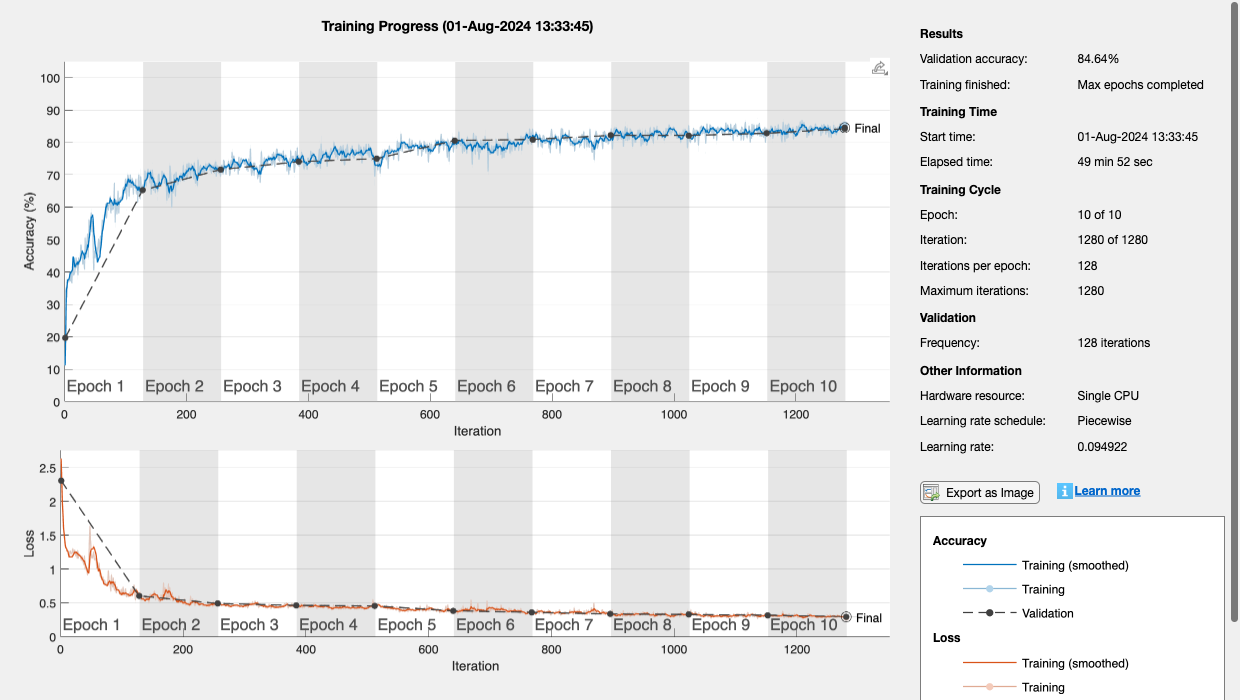

trainedNet = trainNetwork(rxTrainFrames,rxTrainLabels,modClassNet,options);

numel(rxTrainLabels)

ans = 132000

ismember("QPSK", rxTrainLabels)

ans = logical
   1


categories(rxTrainLabels)

ans = 24×1 cell array
    {'OOK'      }
    {'4ASK'     }
    {'8ASK'     }
    {'BPSK'     }
    {'QPSK'     }
    {'8PSK'     }
    {'16PSK'    }
    {'32PSK'    }
    {'16APSK'   }
    {'32APSK'   }
    {'64APSK'   }
    {'128APSK'  }
    {'16QAM'    }
    {'32QAM'    }
    {'64QAM'    }
    {'128QAM'   }
    {'256QAM'   }
    {'AM-SSB-WC'}
    {'AM-SSB-SC'}
    {'AM-DSB-WC'}
    {'AM-DSB-SC'}
    {'FM'       }
    {'GMSK'     }
    {'OQPSK'    }


testFrames = transform(testDSTrans, @helperModClassReadFrame);
rxTestFrames = readall(testFrames,"UseParallel",pctExists);
rxTestFrames = cat(4, rxTestFrames{:});

% Read the test labels into the memory
testLabels = transform(testDSTrans, @helperModClassReadLabel);
rxTestLabels = readall(testLabels,"UseParallel",pctExists);

rxTestPred = classify(trainedNet,rxTestFrames);

Unrecognized function or variable 'trainedNet'.

testAccuracy = mean(rxTestPred == rxTestLabels);
disp("Test accuracy: " + testAccuracy*100 + "%")

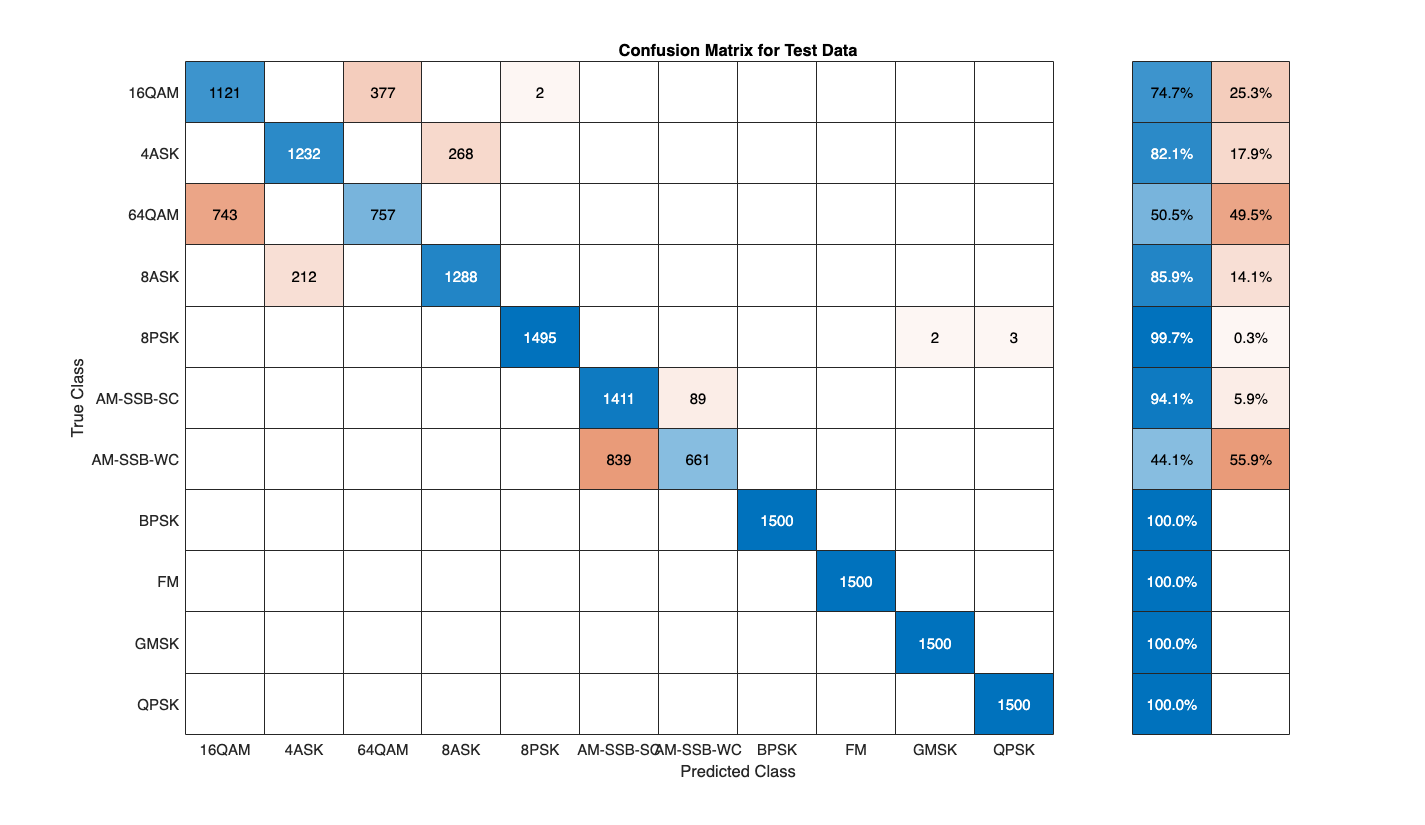

figure
cm = confusionchart(rxTestLabels, rxTestPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 950 550];

## Model 2 with 1 x 16 filter size

sps2 = 16;
spf2 = 1024;
modClassNet2 = helperModClassCNN(modulationTypes,sps2,spf2)

modClassNet2 =   28×1 Layer array with layers:

     1   'Input Layer'   Image Input             1×1024×2 images
     2   'CNN1'          2-D Convolution         16 1×16 convolutions with stride [1  1] and padding 'same'
     3   'BN1'           Batch Normalization     Batch normalization
     4   'ReLU1'         ReLU                    ReLU
     5   'MaxPool1'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
     6   'CNN2'          2-D Convolution         24 1×16 convolutions with stride [1  1] and padding 'same'
     7   'BN2'           Batch Normalization     Batch normalization
     8   'ReLU2'         ReLU                    ReLU
     9   'MaxPool2'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
    10   'CNN3'          2-D Convolution         32 1×16 convolutions with stride [1  1] and padding 'same'
    11   'BN3'        

maxEpochs = 10;
miniBatchSize = 1024;
options = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels)

Unrecognized function or variable 'rxTrainLabels'.

elapsedTime = seconds(toc);
elapsedTime.Format = 'hh:mm:ss';
fprintf('%s - Training the network\n', elapsedTime)

14:53:14 - Training the network


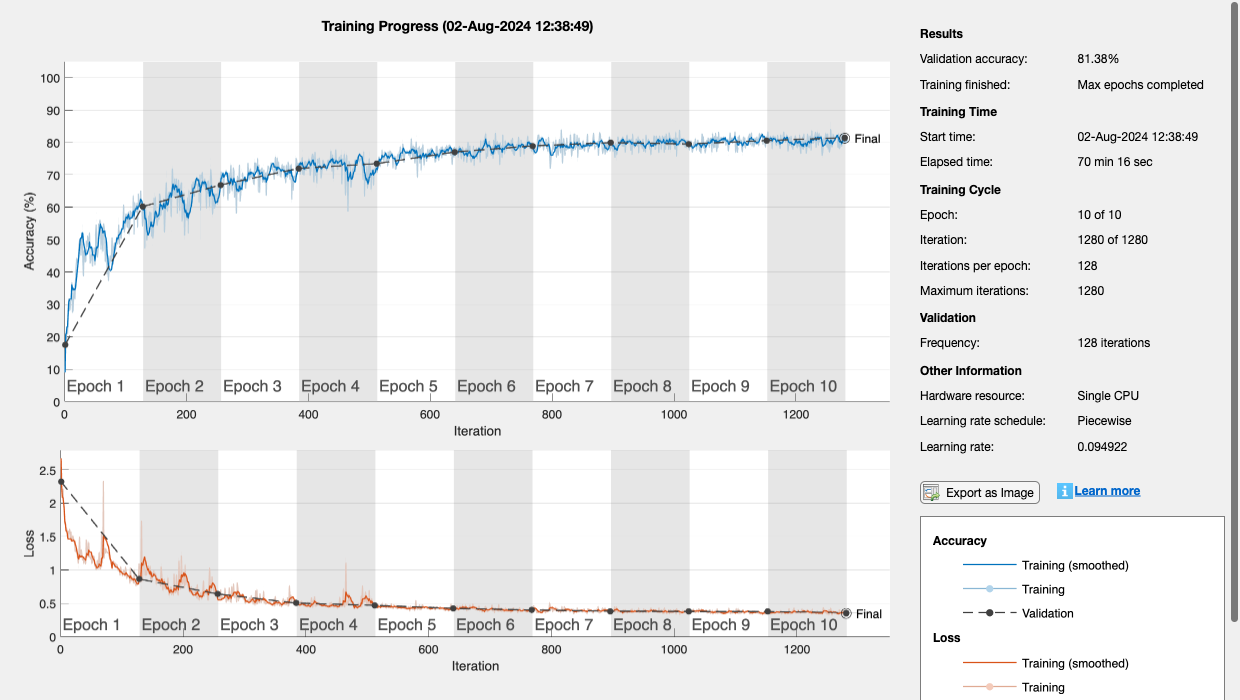

trainedNet2 = trainNetwork(rxTrainFrames,rxTrainLabels,modClassNet2,options);

## Model 3 with 1 x 4 filter size

sps3 = 4;
spf3 = 1024;
modClassNet3 = helperModClassCNN(modulationTypes,sps3,spf3)

modClassNet3 =   28×1 Layer array with layers:

     1   'Input Layer'   Image Input             1×1024×2 images
     2   'CNN1'          2-D Convolution         16 1×4 convolutions with stride [1  1] and padding 'same'
     3   'BN1'           Batch Normalization     Batch normalization
     4   'ReLU1'         ReLU                    ReLU
     5   'MaxPool1'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
     6   'CNN2'          2-D Convolution         24 1×4 convolutions with stride [1  1] and padding 'same'
     7   'BN2'           Batch Normalization     Batch normalization
     8   'ReLU2'         ReLU                    ReLU
     9   'MaxPool2'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
    10   'CNN3'          2-D Convolution         32 1×4 convolutions with stride [1  1] and padding 'same'
    11   'BN3'           

options = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels)

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.2000
                       MaxEpochs: 10
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 1024
                         Shuffle: 'every-epoch'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: {[1×1024×2×16500 single]  [16500×1 categorical]}
             ValidationFrequency: 128
              ValidationP

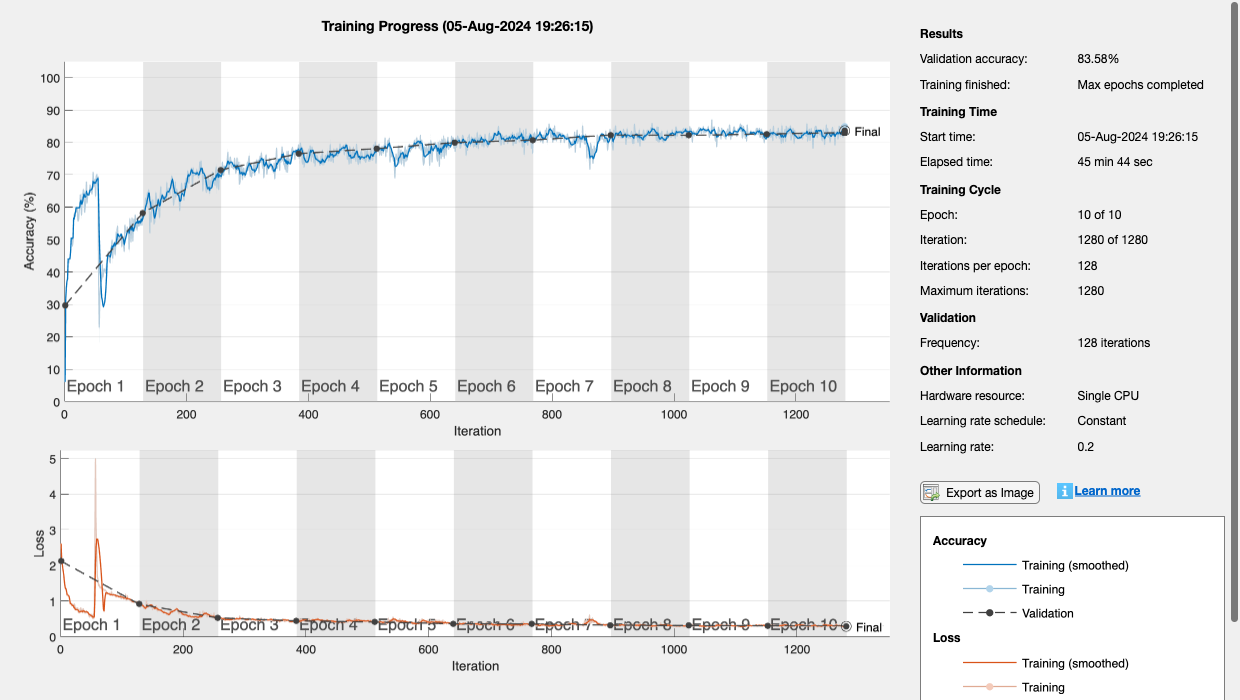

trainedNet3 = trainNetwork(rxTrainFrames,rxTrainLabels,modClassNet3,options);

filterSize = [1, 8];
netWidth = 1;
poolSize = [1 2];
sps4 = 8;
spf4 = 1024;
numModTypes=numel(modulationTypes);
% Define the input layer
inputLayer = imageInputLayer([1 spf4 2], 'Name', 'input', 'Normalization', 'zerocenter');


% Define the initial convolution layer
conv1 = convolution2dLayer(filterSize, 16*netWidth, 'Padding', 'same', 'Name', 'conv1');
relu1 = reluLayer('Name', 'ReLU1');
pool1 = maxPooling2dLayer(poolSize, 'Stride', [1 2], 'Name', 'MaxPool1');

## Model 1 - Convolutional Neural Network

In this section we explore, train and test a small CNN for 20 ephochs on the training set

sps_small = 4;
spf_small = 1024;
modClassNet_model_small = helperModClassCNN(modulationTypes,sps_small,spf_small)

modClassNet_model_small =   28×1 Layer array with layers:

     1   'Input Layer'   Image Input             1×1024×2 images
     2   'CNN1'          2-D Convolution         16 1×4 convolutions with stride [1  1] and padding 'same'
     3   'BN1'           Batch Normalization     Batch normalization
     4   'ReLU1'         ReLU                    ReLU
     5   'MaxPool1'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
     6   'CNN2'          2-D Convolution         24 1×4 convolutions with stride [1  1] and padding 'same'
     7   'BN2'           Batch Normalization     Batch normalization
     8   'ReLU2'         ReLU                    ReLU
     9   'MaxPool2'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
    10   'CNN3'          2-D Convolution         32 1×4 convolutions with stride [1  1] and padding 'same'
    11   'BN3'

options_small = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels)

options_small =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 20
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 1024
                         Shuffle: 'every-epoch'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: {[1×1024×2×16500 single]  [16500×1 categorical]}
             ValidationFrequency: 128
              Valid

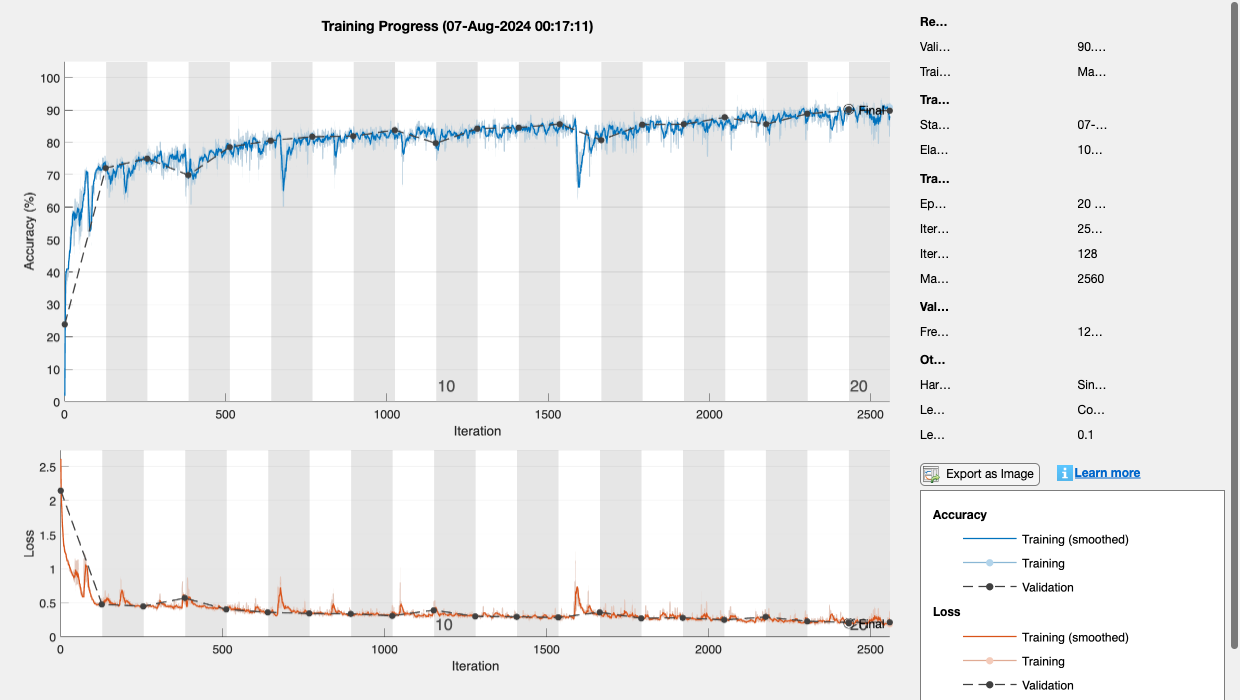

trained_model_small = trainNetwork(rxTrainFramesNew,rxTrainLabelsNew,modClassNet_model_small,options_small);

% testFrames = transform(testDSTrans, @helperModClassReadFrame);
% rxTestFrames = readall(testFrames,"UseParallel",pctExists);
% rxTestFrames = cat(4, rxTestFrames{:});
% 
% % Read the test labels into the memory
% testLabels = transform(testDSTrans, @helperModClassReadLabel);
% rxTestLabels = readall(testLabels,"UseParallel",pctExists);

rxTestPred = classify(trained_model_small,rxTestFrames);
testAccuracy = mean(rxTestPred == rxTestLabels);
disp("Test accuracy: " + testAccuracy*100 + "%")

Test accuracy: 90.2242%


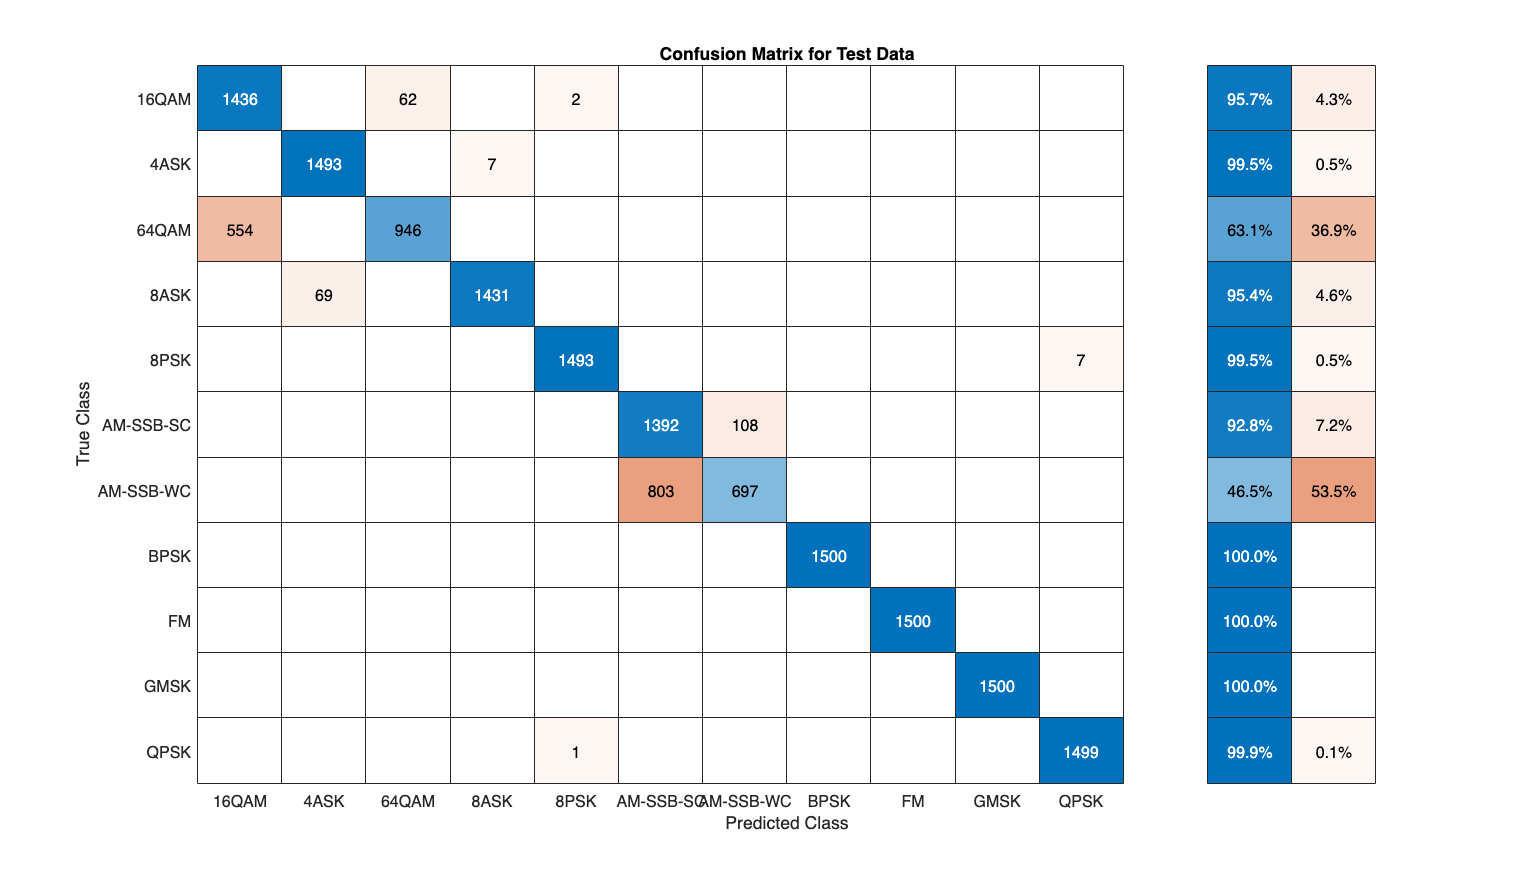

figure
cm = confusionchart(rxTestLabels, rxTestPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 950 550];

% save('trained_model_small.mat', 'trained_model_small');

save('test_label.mat', 'rxTestLabels')

## Model II

sps_small2 = 16;
spf_small2 = 1024;
modClassNet_model_small2 = helperModClassCNN(modulationTypes,sps_small2,spf_small2)

options_small2 = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels)

trained_model_small2 = trainNetwork(rxTrainFramesNew,rxTrainLabelsNew,modClassNet_model_small2,options_small2);

modClassNet_model_small2 =   28×1 Layer array with layers:

     1   'Input Layer'   Image Input             1×1024×2 images
     2   'CNN1'          2-D Convolution         16 1×16 convolutions with stride [1  1] and padding 'same'
     3   'BN1'           Batch Normalization     Batch normalization
     4   'ReLU1'         ReLU                    ReLU
     5   'MaxPool1'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
     6   'CNN2'          2-D Convolution         24 1×16 convolutions with stride [1  1] and padding 'same'
     7   'BN2'           Batch Normalization     Batch normalization
     8   'ReLU2'         ReLU                    ReLU
     9   'MaxPool2'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
    10   'CNN3'          2-D Convolution         32 1×16 convolutions with stride [1  1] and padding 'same'
    11   '

rxTestPred = classify(trained_model_small2,rxTestFrames);
testAccuracy = mean(rxTestPred == rxTestLabels);

options_small2 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 20
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 1024
                         Shuffle: 'every-epoch'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: {[1×1024×2×16500 single]  [16500×1 categorical]}
             ValidationFrequency: 128
              Vali

disp("Test accuracy: " + testAccuracy*100 + "%")

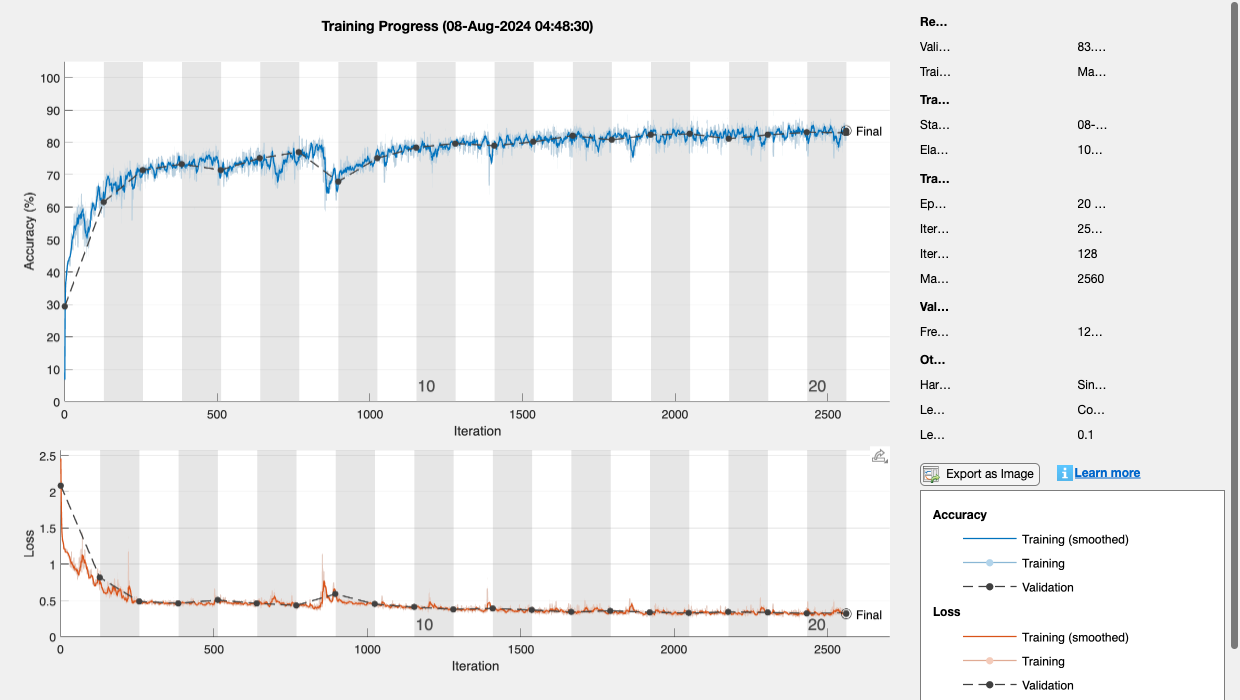

figure

cm = confusionchart(rxTestLabels, rxTestPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 950 550];

Test accuracy: 83.6909%


## Model III

sps_small3 = 8;
spf_small3 = 1024;
modClassNet_model_small3 = helperModClassCNN(modulationTypes,sps_small3,spf_small3)

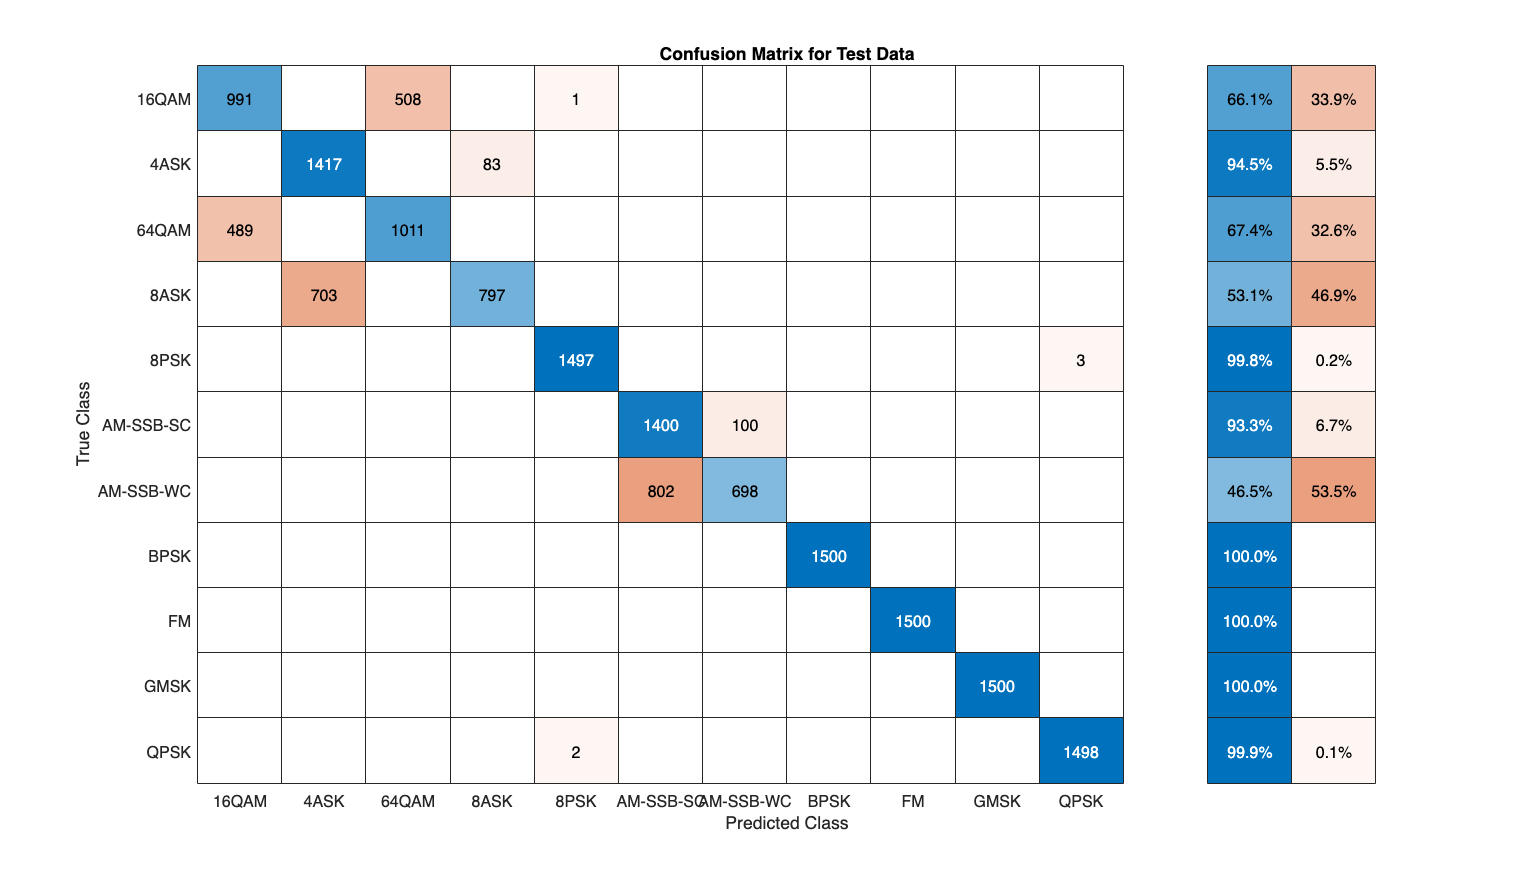

options_small3 = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels)

trained_model_small3 = trainNetwork(rxTrainFramesNew,rxTrainLabelsNew,modClassNet_model_small3,options_small3);

% save('trained_model_small3.mat', 'trained_model_small3');

## Model IV

sps_small4 = 2;
spf_small4 = 1024;

modClassNet_model_small3 =   28×1 Layer array with layers:

     1   'Input Layer'   Image Input             1×1024×2 images
     2   'CNN1'          2-D Convolution         16 1×8 convolutions with stride [1  1] and padding 'same'
     3   'BN1'           Batch Normalization     Batch normalization
     4   'ReLU1'         ReLU                    ReLU
     5   'MaxPool1'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
     6   'CNN2'          2-D Convolution         24 1×8 convolutions with stride [1  1] and padding 'same'
     7   'BN2'           Batch Normalization     Batch normalization
     8   'ReLU2'         ReLU                    ReLU
     9   'MaxPool2'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
    10   'CNN3'          2-D Convolution         32 1×8 convolutions with stride [1  1] and padding 'same'
    11   'BN3

modClassNet_model_small4 = helperModClassCNN(modulationTypes,sps_small4,spf_small4)

options_small4 = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels),rxValidFrames,rxValidLabels)

options_small3 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 20
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 1024
                         Shuffle: 'every-epoch'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: {[1×1024×2×16500 single]  [16500×1 categorical]}
             ValidationFrequency: 128
              Vali

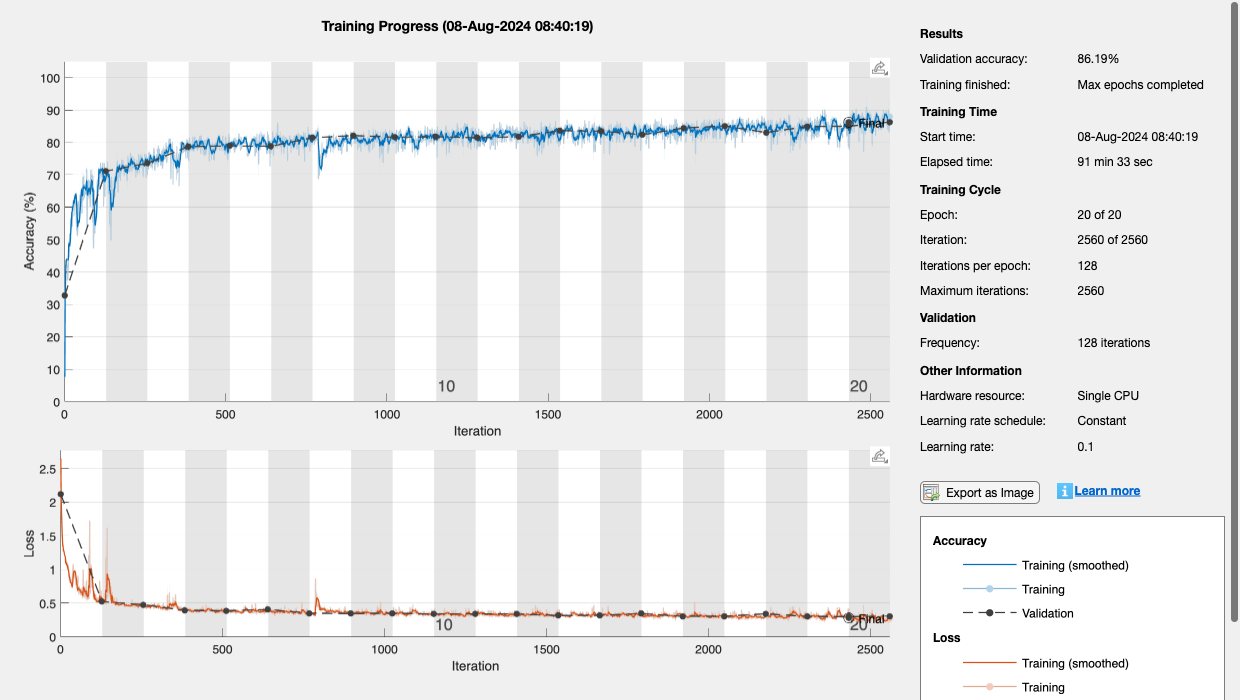

trained_model_small4 = trainNetwork(rxTrainFramesNew,rxTrainLabelsNew,modClassNet_model_small4,options_small4);

% save('trained_model_small4.mat', 'trained_model_small4');

% ------------------ END OF TRAINING ----------------------- %

# Generating Confusion Matrix Per SNR for different models

#### Extract data from orginal data store and group according to SNR levels

snrLocation = 4096 * (i+11) + 1 + 1000;
trainDs = RadioMLDatastore(filePath, "/X", "/Y", "train", 24, 106497, snrLocation);
trainMbds = MiniBatchDatastore(testDs, 24);

modClassNet_model_small4 =   28×1 Layer array with layers:

     1   'Input Layer'   Image Input             1×1024×2 images
     2   'CNN1'          2-D Convolution         16 1×2 convolutions with stride [1  1] and padding 'same'
     3   'BN1'           Batch Normalization     Batch normalization
     4   'ReLU1'         ReLU                    ReLU
     5   'MaxPool1'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
     6   'CNN2'          2-D Convolution         24 1×2 convolutions with stride [1  1] and padding 'same'
     7   'BN2'           Batch Normalization     Batch normalization
     8   'ReLU2'         ReLU                    ReLU
     9   'MaxPool2'      2-D Max Pooling         1×2 max pooling with stride [1  2] and padding [0  0  0  0]
    10   'CNN3'          2-D Convolution         32 1×2 convolutions with stride [1  1] and padding 'same'
    11   'BN3

selectedModIdx = [4 5 13 15 6 2 3 23 18 19 22];
snrValues = 2:2:30;

options_small4 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.1000
                       MaxEpochs: 20
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 1024
                         Shuffle: 'every-epoch'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: {[1×1024×2×16500 single]  [16500×1 categorical]}
             ValidationFrequency: 128
              Vali

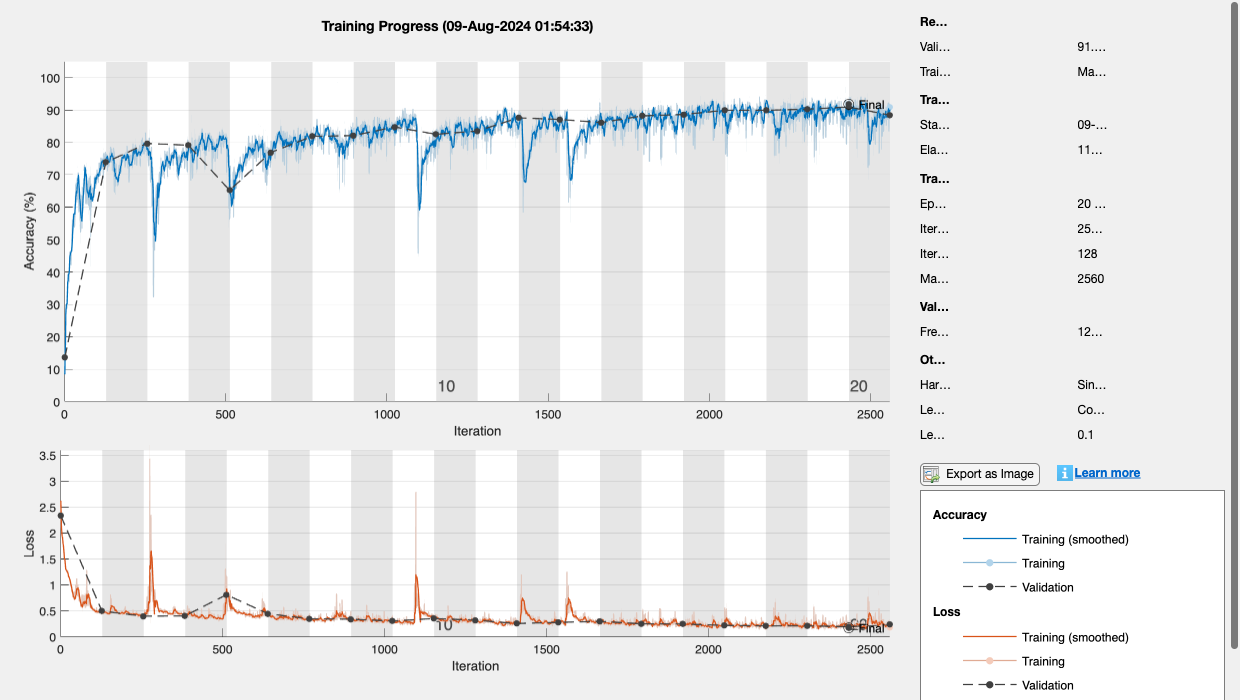

snrArray = cell(1, 15);
for i=1:15

    snrLocation = 4096 * (i+11) + 1 + 1000;
    trainDs = RadioMLDatastore(filePath, "/X", "/Y", "train", 24, 106497, snrLocation);
    trainMbds = MiniBatchDatastore(testDs, 24);

    frameArray = cell(1, 1100);
    labelArray = cell(1, 1100);

    startPos = 0;

    % read datastore
    for j=1:100
        frames = testMbds.read();
        for k=1:length(selectedModIdx)
            idx = selectedModIdx(k);

            frame = frames{idx, 1};
            label = string(frames{idx, 2});
            x = find(modulationTypes == label);
            label = modulationTypes(x);
            cellIdx = (startPos) + k;
            frameArray{cellIdx} = frame;
            labelArray{cellIdx} = label;
        end
        startPos = startPos + 11;
    end
    snrArray{i} = {frameArray, labelArray};
end

#### Redefine models based on filter size and accuracy

model16_82 = load("trained_model_small2.mat");
model8_86 = load("trained_model_small3.mat");
model4_90 = load("trained_model_small.mat");
model2_91 = load("trained_model_small4.mat");

model16_82 = model16_82.trained_model_small2; 
model8_86 = model8_86.trained_model_small3;
model4_90 = model4_90.trained_model_small;
model2_91 = model2_91.trained_model_small4;

SNR_IDX = 1;

#### Extract and separate frames from labels

snr2 = snrArray{1,SNR_IDX};
snr2Frames = snr2(:, 1);
snr2Labels = snr2(:, 2);
snr2Frames = snr2Frames{1, 1};
snr2Labels = snr2Labels{1, 1};
snr2FramesT = cat(4, snr2Frames{:});
snr2LabelsT = cat(2, ...
    snr2Labels{:})';

rxTestPred = classify(model2_91,snr2FramesT);
testAccuracy = mean(rxTestPred == snr2LabelsT);
disp("Test accuracy: " + testAccuracy*100 + "%")

Test accuracy: 90.6364%


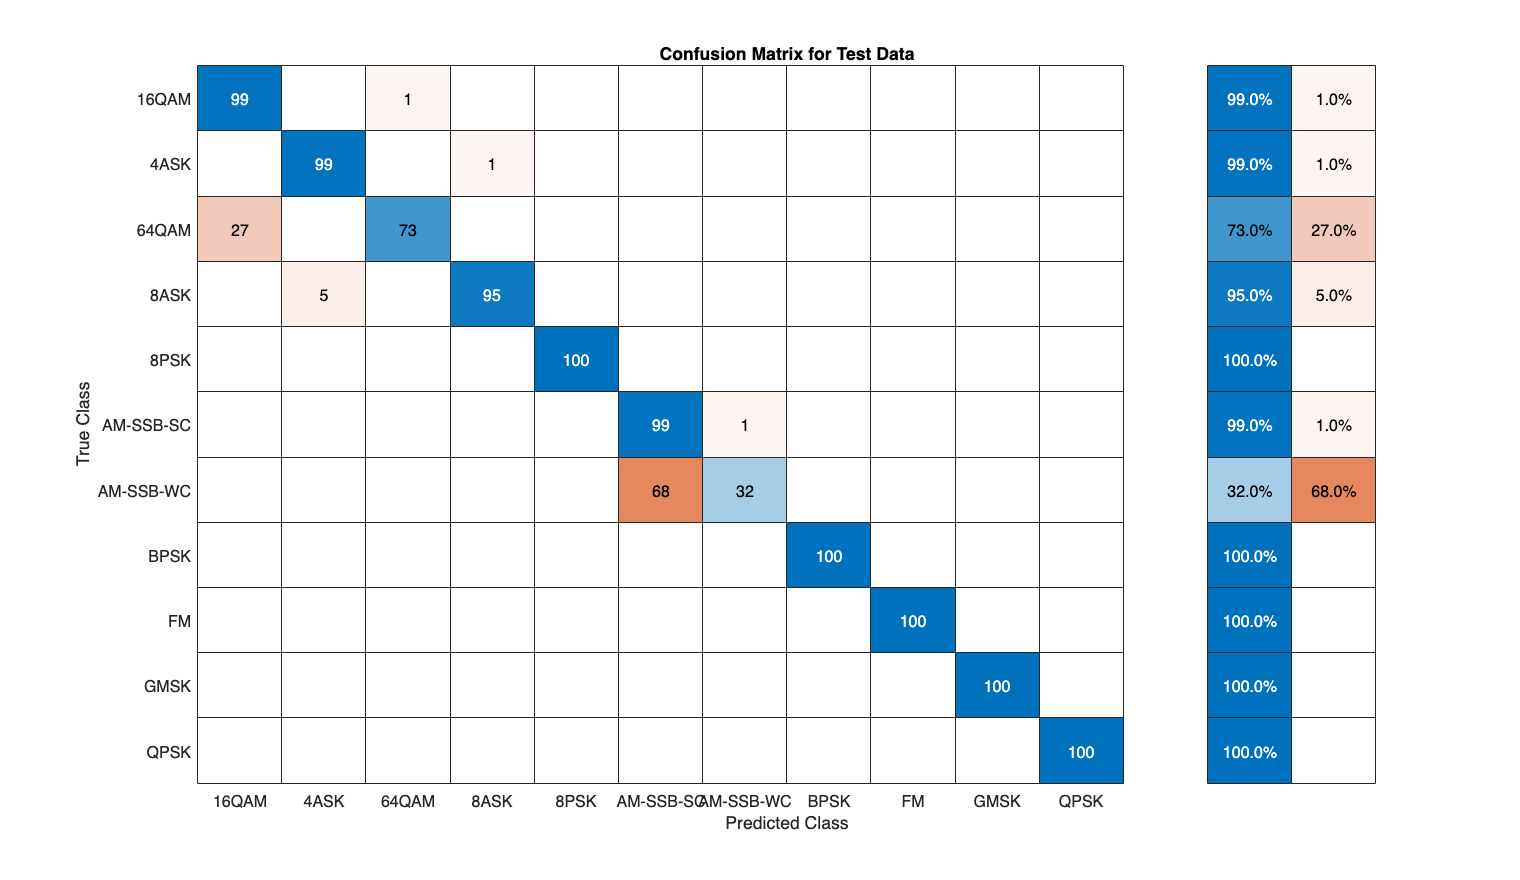

figure
cm = confusionchart(snr2LabelsT, rxTestPred);
% sprintf("", )
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 950 550];

#### Create plot for accuracy vs SNR for each model

SNRVsAccuracy = cell(1, 15);
for i=1:15
    snr2 = snrArray{1,i};
    snr2Frames = snr2(:, 1);
    snr2Labels = snr2(:, 2);
    snr2Frames = snr2Frames{1, 1};
    snr2Labels = snr2Labels{1, 1};
    snr2FramesT = cat(4, snr2Frames{:});
    snr2LabelsT = cat(2, snr2Labels{:})';
    rxTestPred = classify(model2_91,snr2FramesT);
    testAccuracy = mean(rxTestPred == snr2LabelsT);
    SNRVsAccuracy{i} = testAccuracy;
    disp("Test accuracy: " + testAccuracy*100 + "%")
end

Test accuracy: 91.7273%
Test accuracy: 90.3636%
Test accuracy: 90.7273%
Test accuracy: 90.8182%
Test accuracy: 91.9091%
Test accuracy: 91.3636%
Test accuracy: 91.1818%
Test accuracy: 91.8182%
Test accuracy: 91%
Test accuracy: 90.3636%
Test accuracy: 90.8182%
Test accuracy: 91.5455%
Test accuracy: 90.5455%
Test accuracy: 91.7273%
Test accuracy: 92.0909%


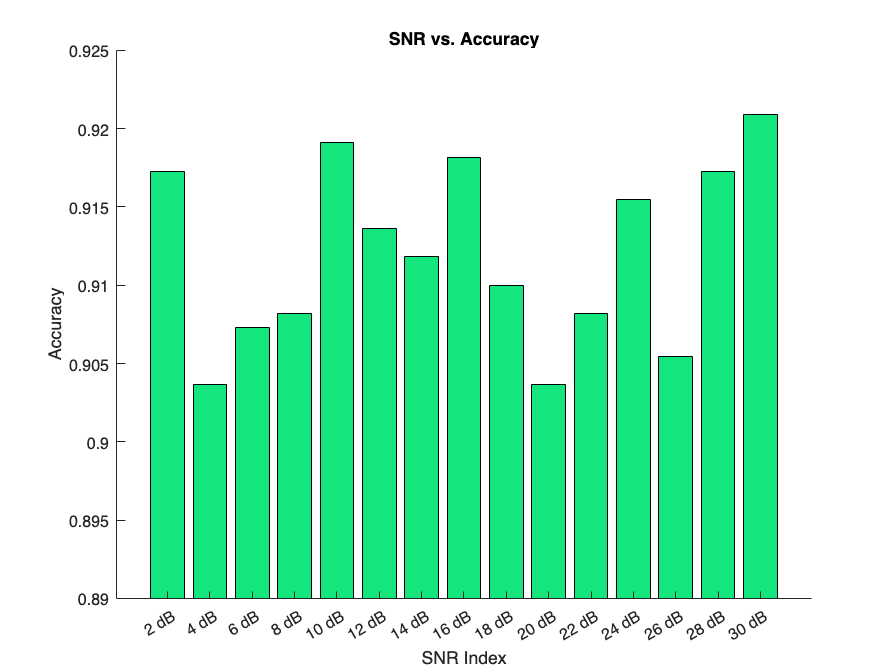

co = [0.08 0.9 0.49;
  0.52 0.95 0.70;
  0.36 0.53 0.96;
  0.09 0.54 0.67;
  0.48 0.99 0.26;
  0.95 0.31 0.17;
  0.52 0.85 0.95;
  0.08 0.72 0.88;
  0.12 0.45 0.69;
  0.22 0.11 0.49;
  0.65 0.54 0.71];
figure; ax = axes('ColorOrder',co,'NextPlot','replacechildren');
bar(ax, cell2mat(SNRVsAccuracy));
xlabel(ax, 'SNR Index');
ylabel(ax, 'Accuracy');
title(ax, 'SNR vs. Accuracy');
xValues = 2:2:30; % Define the x-values
xticks(ax, 1:length(xValues)); % Set the tick positions
xticklabels(ax, strcat(string(xValues), ' dB')); % Set the tick labels
ylim(ax, [0.89 0.925]); % Set the y-axis limits

#### Create plot for best model performance on Test set

rxTestPred = classify(model2_91,rxTestFrames);
testAccuracy = mean(rxTestPred == rxTestLabels);
acc = "Test accuracy: " + testAccuracy*100 + "%";
disp(acc)

Test accuracy: 91.8606%


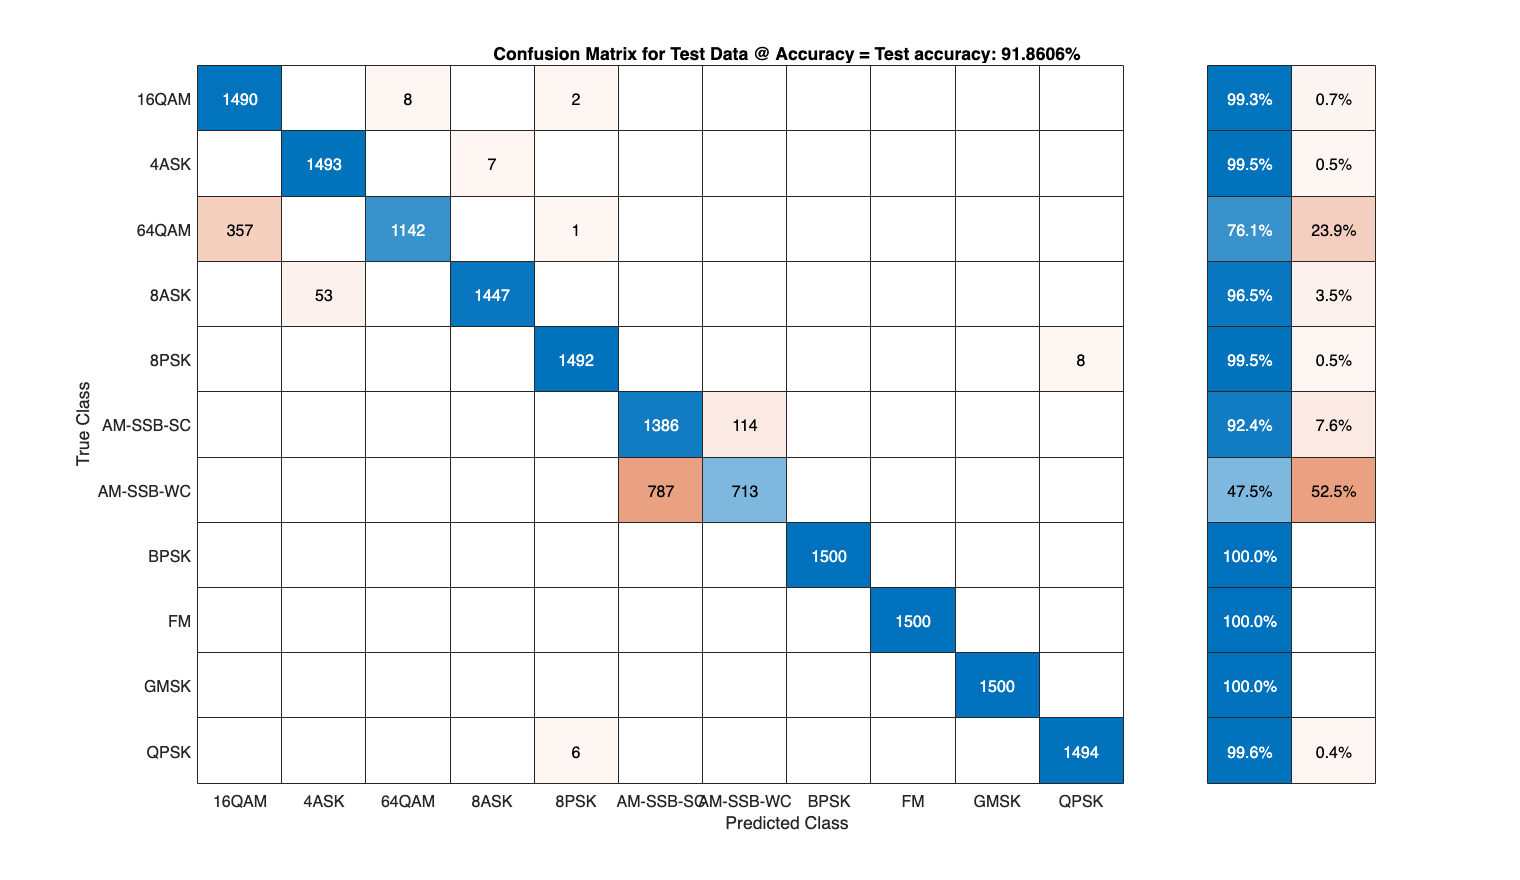

figure
cm = confusionchart(rxTestLabels, rxTestPred);
cm.Title = sprintf('Confusion Matrix for Test Data @ Accuracy = %s', acc);
% cm.FontSize = 14;
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 950 550];

#### Create plot for each model performance on test set.

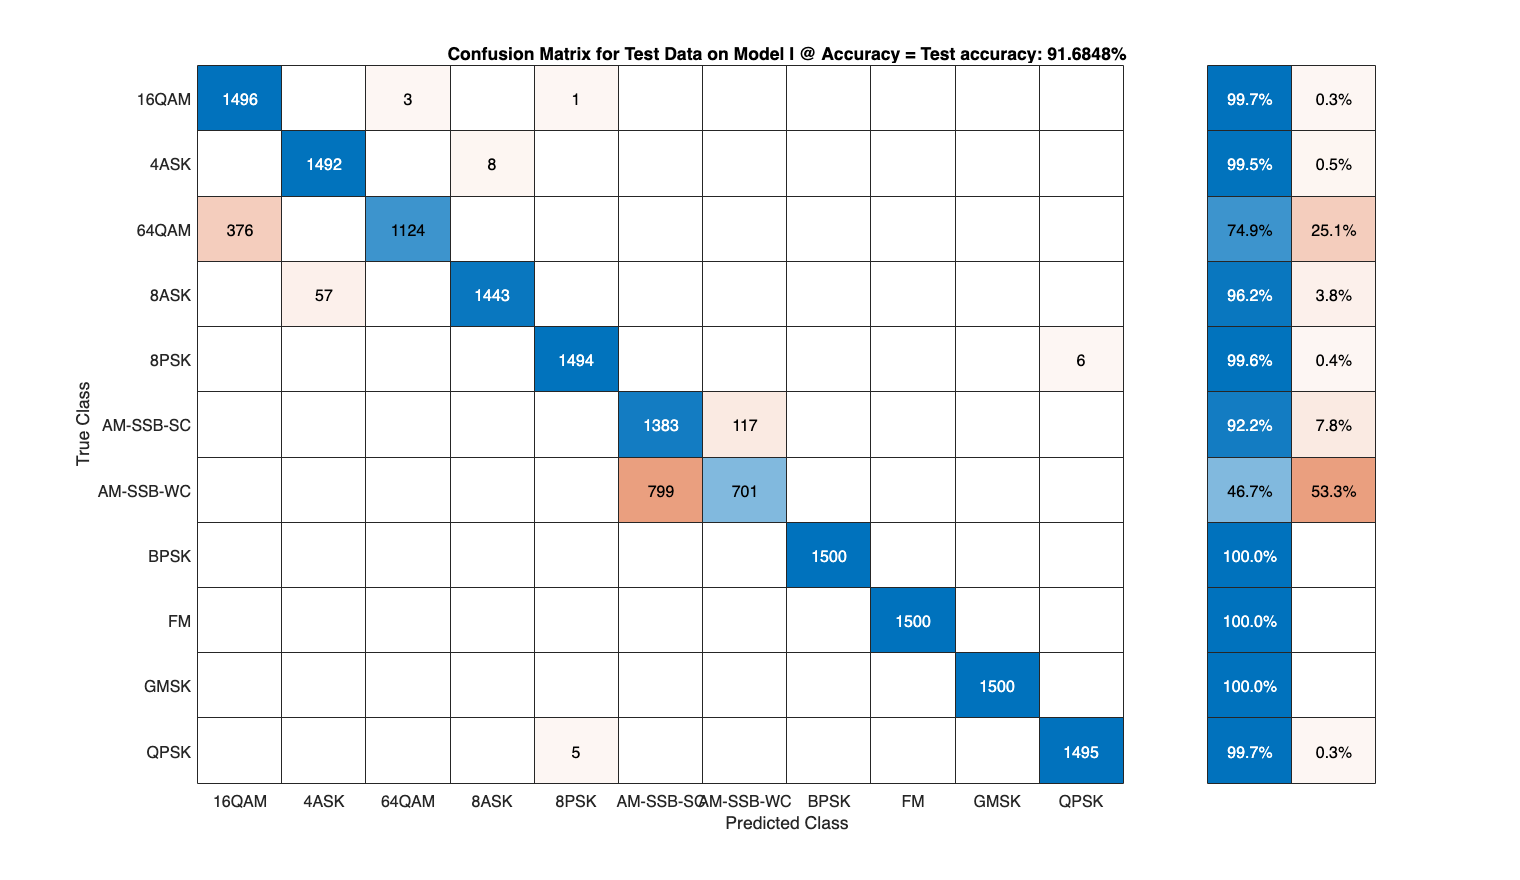

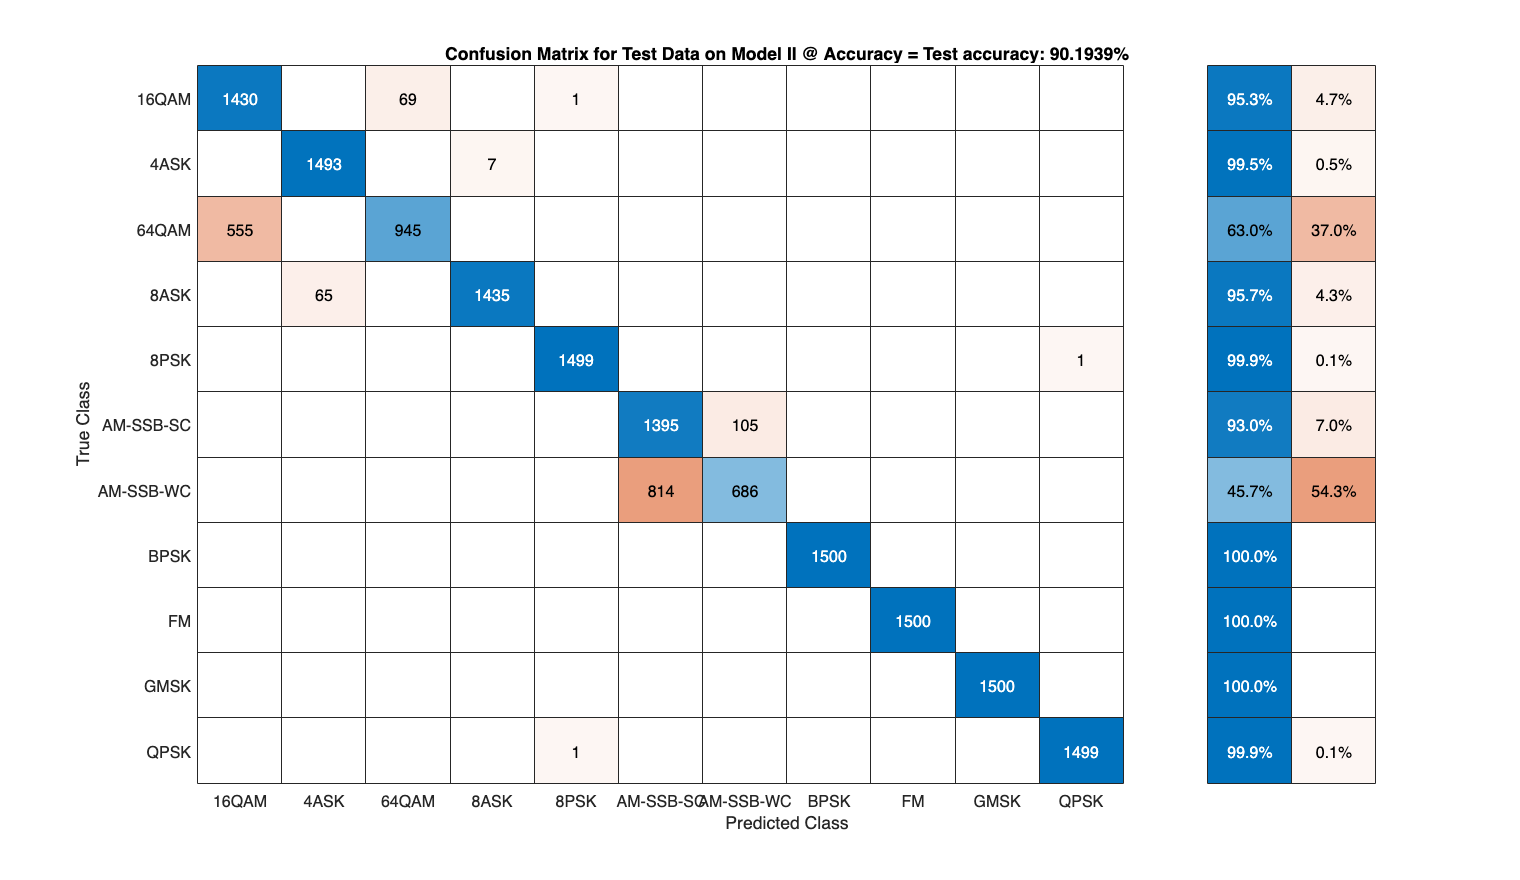

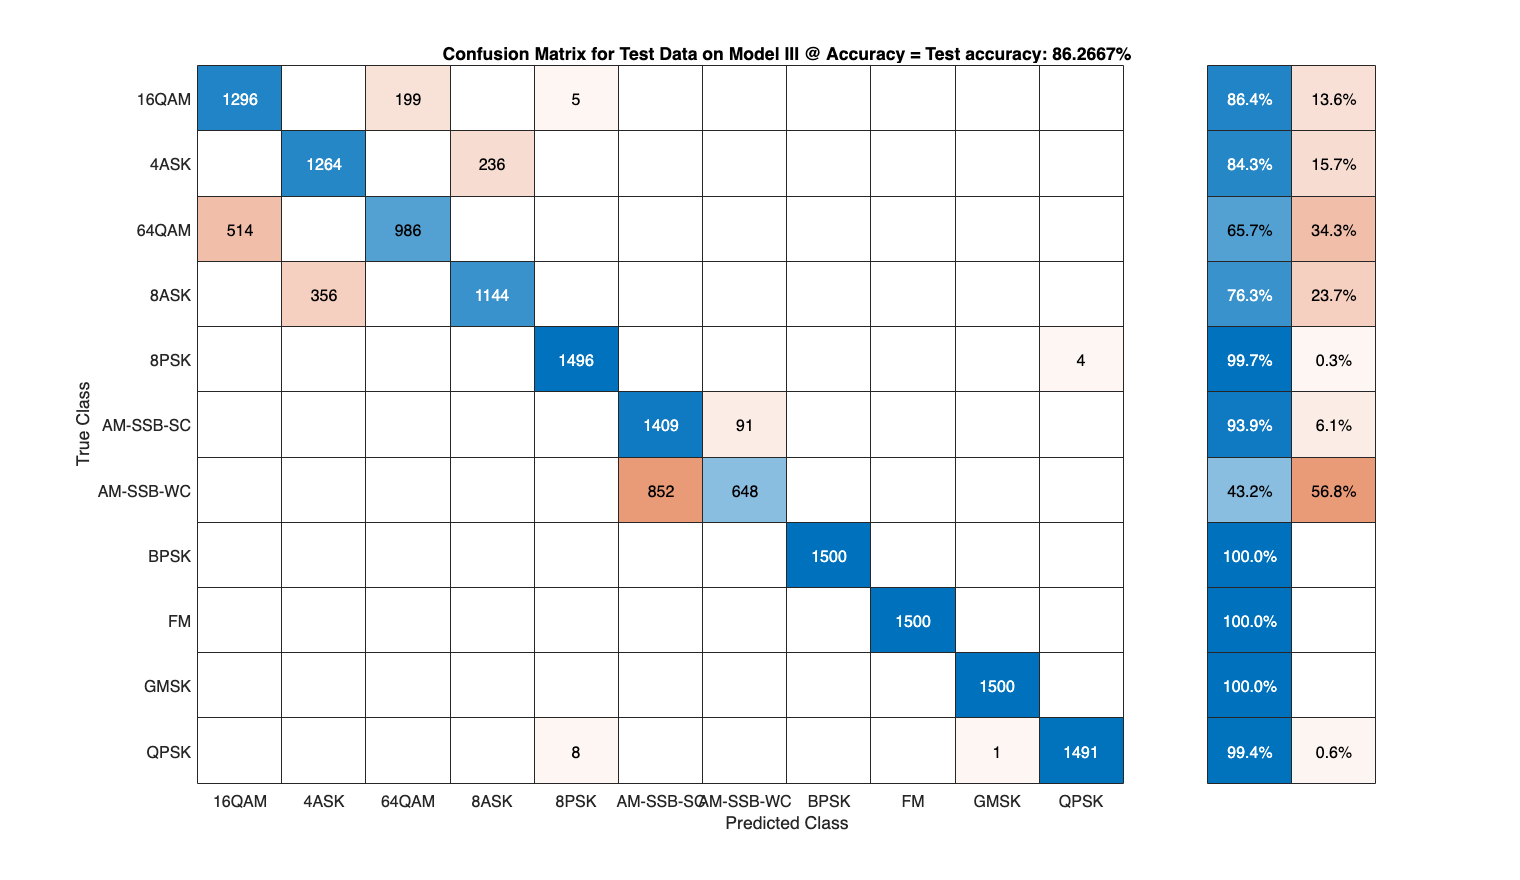

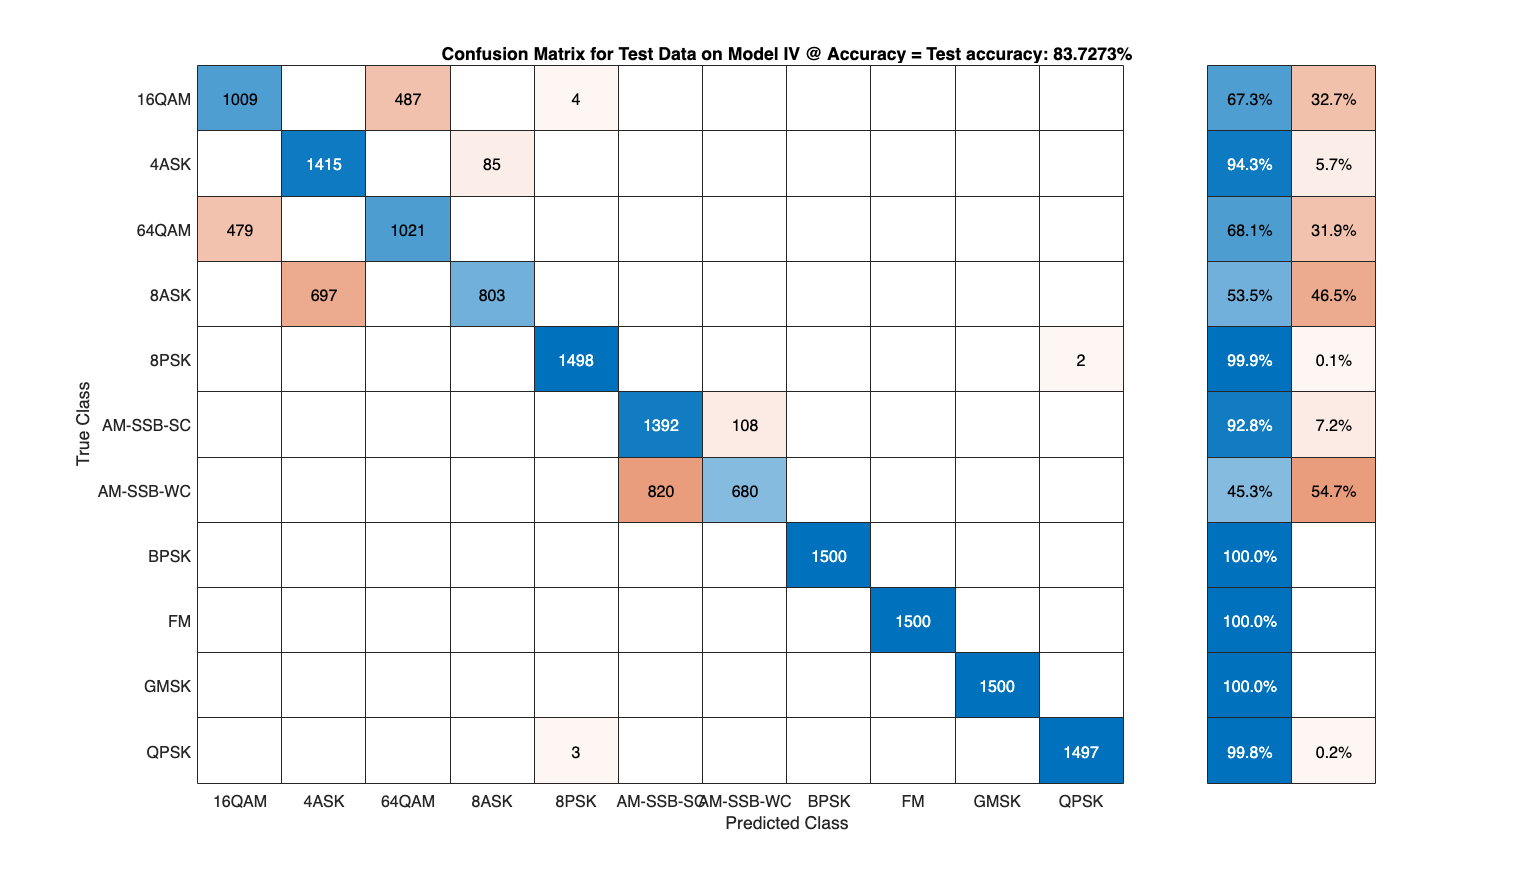

accuracies = ones(1, 4);
models = [model2_91, model4_90, model8_86, model16_82];
modelNames = ["I", "II", "III", "IV"];
for i=1:4
    rxTestPred = classify(models(i),rxTestFrames);
    testAccuracy = mean(rxTestPred == rxTestLabels);
    accuracies(i) = testAccuracy;
    acc = "Test accuracy: " + testAccuracy*100 + "%";

    figure
    cm = confusionchart(rxTestLabels, rxTestPred);
    cm.Title = sprintf('Confusion Matrix for Test Data on Model %s @ Accuracy = %s', modelNames(i), acc);
    % cm.FontSize = 14;
    cm.RowSummary = 'row-normalized';
    cm.Parent.Position = [cm.Parent.Position(1:2) 950 550];
end

accuracies

accuracies =     0.9186    0.9022    0.8619    0.8369


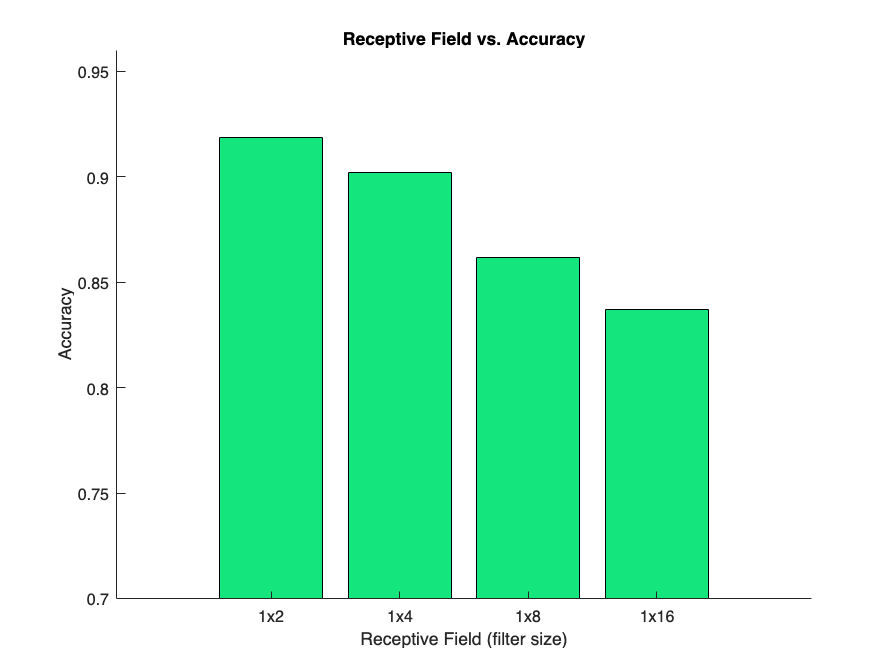

filterSizes = [2, 4, 8, 16];
bar(ax, accuracies);
xlabel(ax, 'Receptive Field (filter size)');
ylabel(ax, 'Accuracy');
title(ax, 'Receptive Field vs. Accuracy');
xValues = 1:1:4; % Define the x-values
xticks(ax, 1:length(xValues)); % Set the tick positions
xticklabels(ax, strcat('1x ', string(filterSizes))); % Set the tick labels
ylim(ax, [0.70 0.96]); % Set the y-axis limits

ans =      1     2     3     4
